clc; clearvars;

rng(0)

clf_f = 50e6;
clk_period = 1/clf_f;

bin_f = 1e6;
bin_period = 1/bin_f;

N_BINS = 100;
CYCLES_PER_BIN = round(bin_period/clk_period);
l = N_BINS*CYCLES_PER_BIN;

pulse_train = NaN(l,1);

bins = (1:N_BINS)';
lam = CYCLES_PER_BIN .* (cos((2*pi .* bins ./ N_BINS) -pi) + 1)/2;

p = poissrnd(lam);

n = 1:l;
ids = ceilDiv(n,CYCLES_PER_BIN);
for i=1:N_BINS
    tmp_id = find(ids==i);
    tmp_train = zeros(CYCLES_PER_BIN,1);
    
    if(p(i)<=CYCLES_PER_BIN)
        tmp_train(1:p(i)) = 1;
        tmp_train = tmp_train(randperm(CYCLES_PER_BIN));

        pulse_train(tmp_id(1):tmp_id(end)) = tmp_train;
    else
        pulse_train(tmp_id) = 1;
    end
end

counts = NaN(N_BINS,1);
for i=1:N_BINS
    tmp_id = ids==i;
    counts(i) = sum(pulse_train(tmp_id));
end

all(counts==p);
test_compare = [counts p];

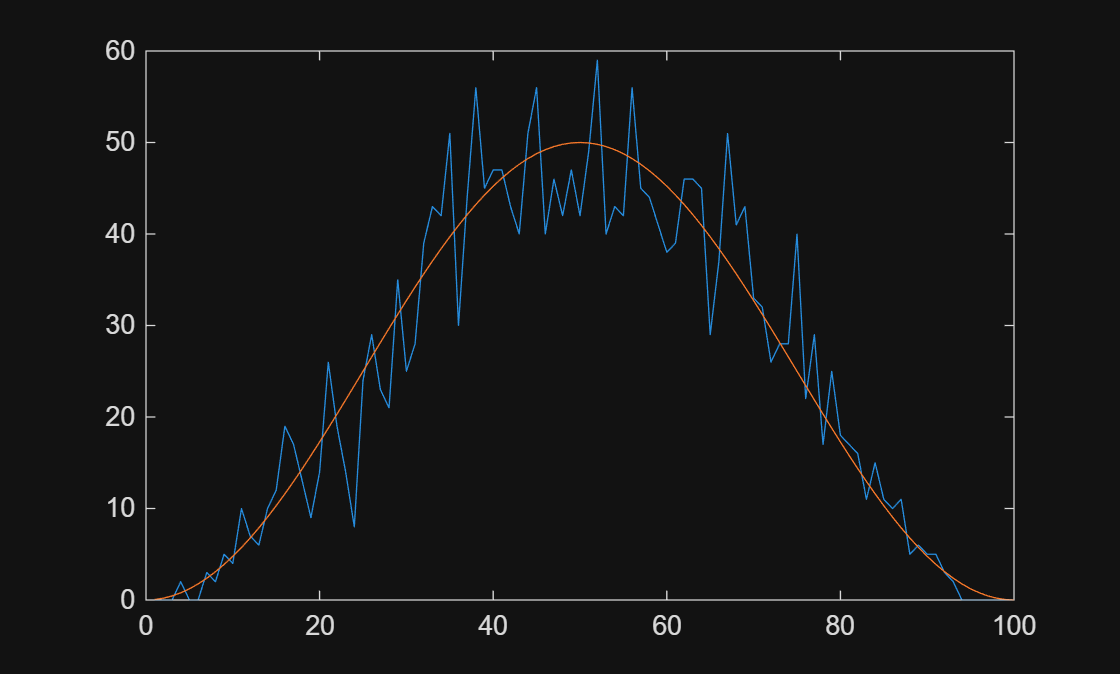

figure;
plot(bins,p)
hold on
plot(bins,lam);
yline(0)
hold off

v = 1;
p(v+1)

ans = 0

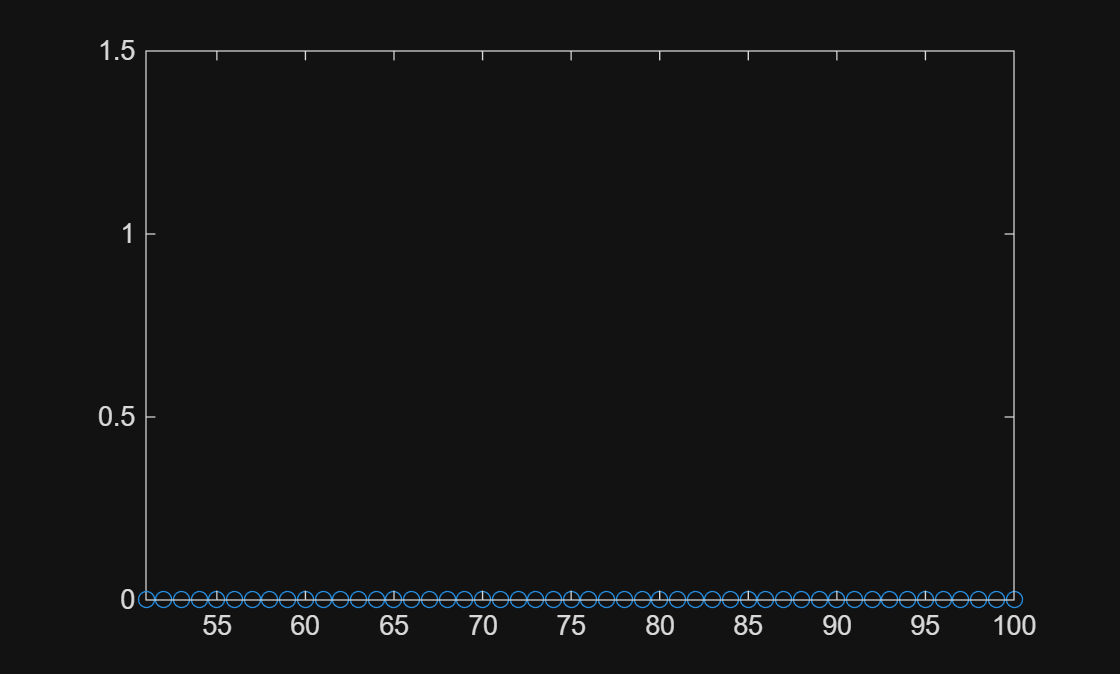


figure;
stem(n,pulse_train)
xlim([CYCLES_PER_BIN.*v+1 (v+1).*CYCLES_PER_BIN])
ylim([0 1.5])

writematrix(pulse_train,"photon_stream.dat");
writematrix(counts,"golden.dat");